Baudrate = 115200;
serialportlist

Undefined function or variable 'serialportlist'.

RpLidar = serialport("COM3", Baudrate, "Timeout", 1, "Parity","odd")
setDTR(RpLidar,false)







% Reset (leave protected mode)
resetStr = 'A540'
resetStrData = sscanf(resetStr, '%2x')
write(RpLidar,resetStrData,"uint8")
readReset = read(RpLidar, 5, "uint8")
dec2hex(readReset)


% Start scan
startStr = 'A521'
startStrData = sscanf(startStr, '%2x')
write(RpLidar,startStr,"uint8")
scandata = read(RpLidar, 59, "uint8")
RpLidar.NumBytesAvailable
dec2bin(scandata, 8)
dec2hex(scandata)

%flush(RpLidar, "output")


% Disconnect
clear RpLidar


stopStr = 'A525'
stopStrData = sscanf(stopStr, '%2x')
write(RpLidar,stopStr,"uint8")
readStop = read(RpLidar, 8, "uint8")
dec2hex(readStop)

% health
str = 'A552';
data = sscanf(str, '%2x');
hexStrWriteData = dec2hex(data)

write(RpLidar, data, "uint8");
readData = read(RpLidar, 10,"uint8");
hexStr = dec2hex(readData)


getInfoStr = 'A550'
getInfoStrData = sscanf(getInfoStr, '%2x')
write(RpLidar,getInfoStrData,"uint8")
readInfo = read(RpLidar, 20,"uint8")
hexStr = dec2hex(readInfo)


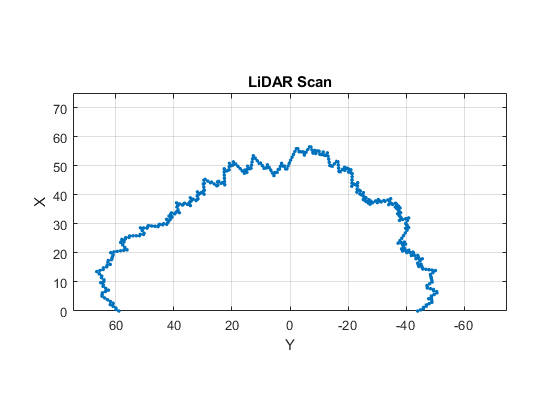

start = randi([40, 50],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end
ranges;


angles = linspace(-pi/2, pi/2, numel(ranges));
scan = lidarScan(ranges, angles);
plot(scan)

## Plot with psuedo randomly generated values


start = randi([15, 20],1,1);
ranges = zeros(1, 360);
ranges(1) = start;

for i = 2:360
    rand_add = randi([-1, 1], 1, 1);
    ranges(i) = ranges(i-1) + rand_add;
    
end



theta = linspace(0, 360, 360);
rho = randi([0, 10], 360, 1);
theta_rad = deg2rad(theta);
polarplot(theta_rad, ranges, '.')
hold on

% obstacle detection
detection_range = 15

detection_range = 15

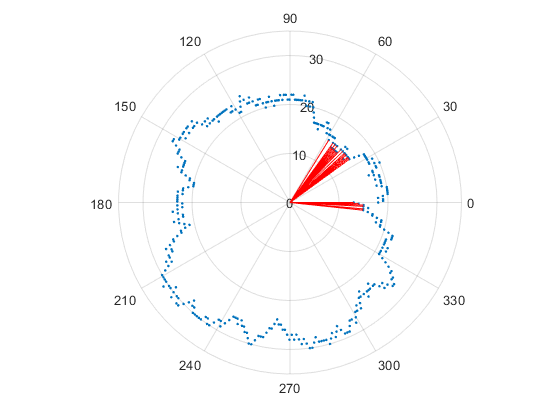

for i = 1:360
    if  abs(ranges(i)) <= detection_range
        line_angle = [theta_rad(i) theta_rad(i)];
        line_range = [0 ranges(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off

## Shape 1 Square without obstacle

% Generate cartesian square
x_v1 = ones(1,45) * 20;
x_v2 = linspace(20, -20, 90);
x_v3 = ones(1, 90) * (-20);
x_v4 = linspace(-20, 20, 90);
x_v5 = ones(1,45) * 20;
x_square = [x_v1 x_v2 x_v3 x_v4 x_v5];

y_v1 = linspace(0, 20, 45);
y_v2 = ones(1,90) * 20;
y_v3 = linspace(20, -20, 90);
y_v4 = ones(1,90) * (-20);
y_v5 = linspace(-20, 0, 45);
y_square = [y_v1 y_v2 y_v3 y_v4 y_v5];


% generate polar cordinates
[theta_square, rho_square] = cart2pol(x_square, y_square);

%plot figure
figure
polarplot(theta_square, rho_square, '.')
hold on


% obstacle detection
detection_range = 15

detection_range = 15

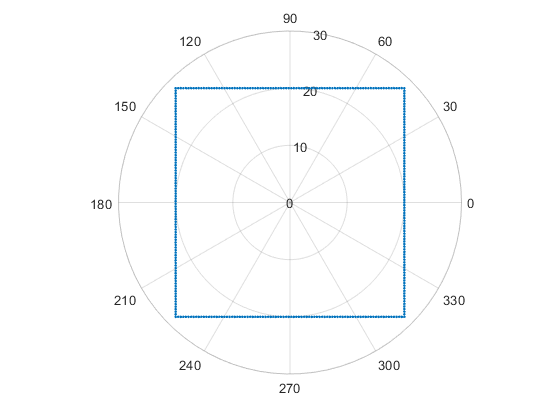

for i = 1:360
    if  abs(rho_square(i)) <= detection_range
        line_angle = [theta_square(i) theta_square(i)];
        line_range = [0 rho_square(i)];
        polarplot(line_angle, line_range, 'r')
    end
end
hold off

## Shape 2 Square with obstacle

theta_square_obst = theta_square;
rho_square_obst = rho_square;

rho_square_obst(22:170) = 15;
rho_square_obst(120:150) = 13

rho_square_obst =    20.0000   20.0052   20.0207   20.0464   20.0825   20.1287   20.1851   20.2515   20.3279   20.4141   20.5100   20.6155   20.7305   20.8547   20.9880   21.1303   21.2813   21.4409   21.6088   21.7850   21.9692   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000   15.0000



% Plot square
figure
polarplot(theta_square_obst, rho_square_obst, '.')
hold on

% Detection
detection_range = 15

detection_range = 15

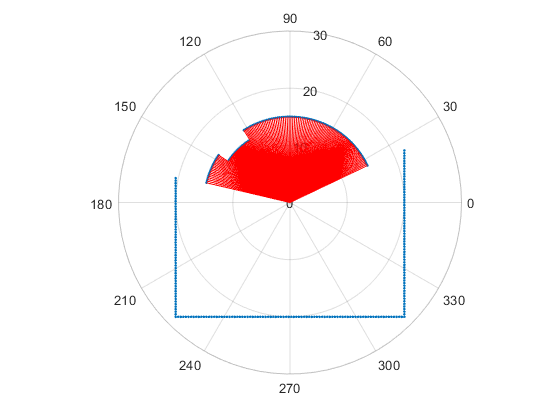

collision_vector = zeros(1,360);
for i = 1:360
    if  abs(rho_square_obst(i)) <= detection_range
        line_angle = [theta_square_obst(i) theta_square_obst(i)];
        line_range = [0 rho_square_obst(i)];
        polarplot(line_angle, line_range, 'r')
        collision_vector(i) = 1;
    end
end
hold off


% Avoid obstacle

collision_angles = find(collision_vector == 1);
number_of_collisions = size(collision_angles);

direction = 1; % 1 = forward, 2 = backward, 3 = right, 4 = left

Zone_A = true;  % 337.5 - 22.5
Zone_B = true;  % 22.5 - 67.5
Zone_C = true;  % 67.5 - 112.5
Zone_D = true;  % 112.5 - 157.5
Zone_E = true;  % 157.5 - 202.5
Zone_F = true;  % 202.5 - 247.5
Zone_G = true;  % 247.5 - 292.5
Zone_H = true;  % 292.5 - 337.5


for i = 1:number_of_collisions(1,2)
    if (collision_angles(i) <= 22.5) && (collision_angles(i) >= 337.5)
        Zone_A = false;
    
    elseif (collision_angles(i) <= 67.5) && (collision_angles(i) >= 22.5)
        Zone_B = false;
        
    elseif (collision_angles(i) <= 112.5) && (collision_angles(i) >= 67.5)
        Zone_C = false;
        
    elseif (collision_angles(i) <= 157.5) && (collision_angles(i) >= 112.5)
        Zone_D = false;
        
    elseif (collision_angles(i) <= 202.5) && (collision_angles(i) >= 157.5)
        Zone_E = false;
        
    elseif (collision_angles(i) <= 247.5) && (collision_angles(i) >= 202.5)
        Zone_F = false;
        
    elseif (collision_angles(i) <= 292.5) && (collision_angles(i) >= 247.5)
        Zone_G = false;
        
    elseif (collision_angles(i) <= 337.5) && (collision_angles(i) >= 292.5)
        Zone_H = false;
        
    end
    
end



if direction == 1

    if Zone_C == true
        disp("F")
        
    elseif (Zone_B == false) || (Zone_A == false)
        if Zone_D == true
            disp("FL")
        elseif (Zone_D == false) && (Zone_E == true)
            disp("L")
        elseif Zone_B == true
            disp ("FR")
        elseif Zone_A == true
            disp ("R")
            
        end
        
    elseif (Zone_D == false) || (Zone_E == false)
        if Zone_B == true
            disp("FR")
        elseif (Zone_B == false) && (Zone_A == true)
            disp("R")
        elseif Zone_D == true
            disp ("FL")
        elseif Zone_E == true
            disp ("L")
        else
            disp("Error 001")
        end
    end
    
    
elseif direction == 2
    
    if Zone_G == true
        disp("B")
        
    elseif (Zone_H == false) || (Zone_A == false)
        if Zone_F == true
            disp("BL")
        elseif (Zone_F == false) && (Zone_E == true)
            disp("L")
        elseif Zone_H == true
            disp ("BR")
        elseif Zone_A == true
            disp ("R")
        end
        
    elseif (Zone_E == false) || (Zone_F == false)
        if Zone_H == true
            disp("BR")
        elseif (Zone_H == false) && (Zone_A == true)
            disp("R")
        elseif Zone_F == true
            disp ("BL")
        elseif Zone_E == true
            disp ("L")
        else
            disp("Error 002")
        end
    end
    
    
elseif direction == 3
    
    if Zone_A == true
        disp("R")
        
    elseif (Zone_G == false) || (Zone_H == false)
        if Zone_B == true
            disp("FR")
        elseif (Zone_B == false) && (Zone_C == true)
            disp("F")
        elseif Zone_H == true
            disp ("BR")
        elseif Zone_G == true
            disp ("B")
        end
        
    elseif (Zone_C == false) || (Zone_B == false)
        if Zone_H == true
            disp("BR")
        elseif (Zone_H == false) && (Zone_G == true)
            disp("B")
        elseif Zone_B == true
            disp ("FR")
        elseif Zone_C == true
            disp ("F")
        else
            disp("Error 003")
        end
    end
    
    
    
elseif direction == 4
    
    if Zone_E == true
        disp("L")
        
    elseif (Zone_F == false) || (Zone_G == false)
        if Zone_D == true
            disp("FL")
        elseif (Zone_D == false) && (Zone_C == true)
            disp("F")
        elseif Zone_F == true
            disp ("BL")
        elseif Zone_G == true
            disp ("B")
        end
        
    elseif (Zone_D == false) || (Zone_C == false)
        if Zone_F == true
            disp("BL")
        elseif (Zone_F == false) && (Zone_G == true)
            disp("B")
        elseif Zone_D == true
            disp ("FL")
        elseif Zone_C == true
            disp ("F")
        else
            disp("Error 004")
        end
    end
    
end

R
